# Harmoniser (ensures non-invasive control)

close all;
clear all;

% define parameters for CL_model_reset (needed for CL control initialization)
w0 = 6.0400

w0 = 6.0400

w0 = 2*pi;
target = 5.9132;
target = 5;
x_init = [0, 0];
periods = 30;
dt = 1/1000;

tracking_tol = 5/100; % 0.1 percent
invasive_tol = 5/100;

% TEST HARMONIZER NEWTON
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);

% get non-invasive control at target response amplitude
[experiment, input3, trial3, control2] = harmonizer_newton(invasive_tol, model, input, trial, control);

Kd = 239.7000

Kp = 239.7000

ans = "get_response_target: response amp -> 5.0044"

ans = "get_response_target: response amp -> 5.0025"

ans = "Harmony Loop: 2 -> invasiveness: 59.1871"

ans =     1.7209  -53.5412         0    5.0000
   -0.1266   -0.1356    0.0010    0.0010
    1.8906  -31.6494    0.0010    0.0010
   -0.5718   -0.6564    0.0010    0.0010
   -0.7452   -1.0422    0.0010    0.0010
   -1.2152   -1.5321    0.0010    0.0010
   -1.6135   -2.1229    0.0010    0.0010


ans = "get_response_target: response amp -> 5.0026"

ans = "Harmony Loop: d2 -> invasiveness: 59.1575"

ans =     1.3852  -53.5499         0    5.0000
   -0.1220   -0.1274    0.0009    0.0009
    1.3093  -31.6624    0.0009    0.0009
   -0.5589   -0.6091    0.0009    0.0009
   -0.7325   -0.9663    0.0009    0.0009
   -1.2087   -1.4106    0.0009    0.0009
   -1.6203   -1.9471    0.0009    0.0009


ans = "get_response_target: response amp -> 4.8876"

ans = "Harmony Loop: 3 -> invasiveness: 137.3477"

ans =    41.7003  -25.0927         0    5.0000
   -1.5866    4.8969   -0.0004    0.0002
  -18.3409  -64.2787    0.0008    0.1230
   -0.5932   -0.5325   -0.0012    0.0003
    0.1086    1.1247   -0.0019    0.0003
    7.7786   -6.2647   -0.0083    0.0004
  -21.0372  -11.6041    0.0130    0.0004


ans = "get_response_target: response amp -> 4.8955"

ans = "Harmony Loop: d3 -> invasiveness: 132.1123"

ans =    41.5762  -25.1837         0    5.0000
   -1.5270    4.8777   -0.0004    0.0002
  -18.2058  -61.5833    0.0008    0.1145
   -0.6070   -0.5361   -0.0011    0.0003
    0.1097    1.0667   -0.0018    0.0003
    7.1221   -5.9289   -0.0078    0.0003
  -19.8680  -10.3996    0.0121    0.0004


ans = "get_response_target: response amp -> 5.0782"

ans = "Harmony Loop: 4 -> invasiveness: 27.9454"

ans =    -9.9264  -51.0724         0    5.0000
    0.1709    0.2303    0.0003   -0.0030
   -1.7862   -7.5511   -0.0070   -0.0784
    0.5075   -3.4021   -0.0048    0.0034
    8.7527  -11.6098   -0.0152   -0.0001
    0.7949   -2.0696   -0.0016   -0.0001
    0.5033   -5.9856   -0.0031    0.0001


ans = "get_response_target: response amp -> 5.0745"

ans = "Harmony Loop: d4 -> invasiveness: 26.52"

ans =    -9.6240  -51.2099         0    5.0000
    0.1595    0.2209    0.0003   -0.0029
   -2.4341   -8.5082   -0.0066   -0.0745
    0.5636   -3.2183   -0.0046    0.0032
    8.6604  -10.7681   -0.0144   -0.0001
    0.8291   -1.9358   -0.0015   -0.0001
    0.7289   -5.6590   -0.0029    0.0001


ans = "get_response_target: response amp -> 5.1244"

ans = "Harmony Loop: 5 -> invasiveness: 103.3736"

ans =    13.8994  -49.4546         0    5.0000
    0.1220    0.0165    0.0001    0.0007
   -0.2212    2.8665   -0.0079   -0.1094
    2.2326    3.4038   -0.0070    0.0003
  -16.8474  -50.3605    0.0568   -0.0000
    0.0986    4.8802   -0.0034   -0.0000
   -1.0095    5.2288   -0.0034    0.0000


ans = "get_response_target: response amp -> 5.1179"

ans = "Harmony Loop: d5 -> invasiveness: 97.7911"

ans =    13.6105  -49.6575         0    5.0000
    0.1162    0.0147    0.0001    0.0006
    0.9683    1.5578   -0.0075   -0.1037
    2.1948    3.1763   -0.0067    0.0002
  -17.4662  -47.2252    0.0539   -0.0000
    0.2661    4.6222   -0.0032   -0.0000
   -0.7429    4.9987   -0.0032    0.0000


ans = "get_response_target: response amp -> 5.1682"

ans = "Harmony Loop: 6 -> invasiveness: 248.4383"

ans =    15.5369  -49.1218         0    5.0000
   -0.2385   -0.2263   -0.0000    0.0003
    1.5117   -1.0426   -0.0079   -0.0970
   -3.4071   -7.9276    0.0144    0.0001
  -17.8228 -126.7494    0.1368   -0.0000
   -0.6637    4.7644   -0.0035   -0.0000
   -0.7336    2.5920   -0.0027   -0.0000


ans = "get_response_target: response amp -> 5.1498"

ans = "Harmony Loop: d6 -> invasiveness: 222.6068"

ans =    15.2657  -49.4394         0    5.0000
   -0.2158   -0.2000   -0.0000    0.0003
    3.7261   -2.9964   -0.0071   -0.0873
   -3.2518   -7.0509    0.0130    0.0001
  -19.6147 -113.5001    0.1231   -0.0000
   -0.4401    4.3107   -0.0031   -0.0000
   -0.5685    2.3682   -0.0025   -0.0000


ans = "get_response_target: response amp -> 5.2364"

ans = "Harmony Loop: 7 -> invasiveness: 500.951"

ans =    15.8073  -48.5076         0    5.0000
    0.2611    0.0853    0.0000    0.0000
   -1.0411   -2.2063   -0.0084   -0.1022
    3.7838    8.8060   -0.0172    0.0000
  -25.8408 -254.2664    0.2729   -0.0000
   -0.7058    4.2611   -0.0024    0.0000
    1.8226   -1.3922   -0.0015    0.0000


ans = "get_response_target: response amp -> 5.2075"

ans = "Harmony Loop: d7 -> invasiveness: 448.11"

ans =    15.5429  -48.9184         0    5.0000
    0.2300    0.0773    0.0000    0.0000
    1.4481   -3.9453   -0.0076   -0.0919
    3.5932    7.8425   -0.0155    0.0000
  -30.4340 -227.9846    0.2456   -0.0000
   -0.4983    3.8577   -0.0022    0.0000
    1.5640   -1.3068   -0.0014    0.0000


ans = "get_response_target: response amp -> 5.3949"

ans = "Harmony Loop: 8 -> invasiveness: 799.0958"

ans =    15.9275  -47.3794         0    5.0000
   -0.3298   -0.3379    0.0000   -0.0000
   -5.8210   -2.5957   -0.0080   -0.1151
   -3.5928  -10.0952    0.0170    0.0000
  -26.9956 -398.5140    0.4264   -0.0000
   -0.3225    2.9115   -0.0016   -0.0000
    4.8290   -5.1424   -0.0004   -0.0000


ans = "get_response_target: response amp -> 5.348"

ans = "Harmony Loop: d8 -> invasiveness: 712.1984"

ans =    16.0060  -47.8697         0    5.0000
   -0.2894   -0.3054    0.0000   -0.0000
   -2.7312   -4.2062   -0.0072   -0.1036
   -3.2372   -9.0818    0.0153    0.0000
  -24.2926 -358.6582    0.3838   -0.0000
   -0.2913    2.6235   -0.0014   -0.0000
    4.3247   -4.6008   -0.0004   -0.0000


ans = "get_response_target: response amp -> 5.1381"

ans = "Harmony Loop: 9 -> invasiveness: 19.9377"

ans =   -10.0442  -49.9018         0    5.0000
    0.0073    0.0071    0.0000    0.0000
    7.9250    6.3398   -0.0065   -0.1337
    0.0660   -0.0759   -0.0002    0.0000
    2.0459    1.6399    0.0005   -0.0000
   -0.0212    0.0670    0.0001    0.0000
   -0.0682   -0.0196   -0.0000   -0.0000


ans = "get_response_target: response amp -> 5.1314"

ans = "Harmony Loop: d9 -> invasiveness: 15.9471"

ans =    -7.2314  -50.5265         0    5.0000
    0.0061    0.0075    0.0000    0.0000
    5.7109    5.7999   -0.0062   -0.1270
    0.0777   -0.0556   -0.0002    0.0000
    1.4346    2.0320    0.0005   -0.0000
   -0.0399    0.0537    0.0001    0.0000
   -0.0496   -0.0403   -0.0000   -0.0000


ans = "get_response_target: response amp -> 5.0596"

ans = "Harmony Loop: 10 -> invasiveness: 27.6782"

ans =    -1.1852  -52.4757         0    5.0000
    0.0047    0.0036    0.0000    0.0000
    0.4894  -14.5198   -0.0054   -0.0552
    0.1296   -0.0118   -0.0002    0.0000
   -0.0684    1.0939    0.0004   -0.0000
   -0.0712    0.0198    0.0001    0.0000
    0.0109   -0.0129   -0.0000   -0.0000


ans = "get_response_target: response amp -> 5.0568"

ans = "Harmony Loop: d10 -> invasiveness: 29.2295"

ans =    -1.1905  -52.5298         0    5.0000
    0.0044    0.0034    0.0000    0.0000
    0.3091  -15.3550   -0.0051   -0.0524
    0.1231   -0.0105   -0.0002    0.0000
   -0.0587    1.0381    0.0004   -0.0000
   -0.0676    0.0191    0.0001    0.0000
    0.0106   -0.0114   -0.0000   -0.0000


ans = "get_response_target: response amp -> 5.1077"

ans = "Harmony Loop: 11 -> invasiveness: 3.8741"

ans =    -2.8126  -51.4539         0    5.0000
    0.0010    0.0070    0.0000    0.0000
    1.9963    0.0046   -0.0046   -0.1032
   -0.0012    0.0039    0.0000    0.0000
    0.4749    1.9376    0.0003   -0.0000
   -0.0005    0.0008    0.0000   -0.0000
   -0.0457   -0.0214    0.0000   -0.0000


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -2.8126  -51.4539         0    5.0000
    0.0010    0.0070    0.0000    0.0000
    1.9963    0.0046   -0.0046   -0.1032
   -0.0012    0.0039    0.0000    0.0000
    0.4749    1.9376    0.0003   -0.0000
   -0.0005    0.0008    0.0000   -0.0000
   -0.0457   -0.0214    0.0000   -0.0000


A_coeffs = experiment.A_responses;%(:, 1:harmony_count);
B_coeffs = experiment.B_responses;%(:, 1:harmony_count);
% iter_num = (0:harmony_count-1);
iter_num = (0:size(A_coeffs, 2)-1);
figure;
t = tiledlayout(2, 2, "TileSpacing","compact")

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'compact'

  Show all properties


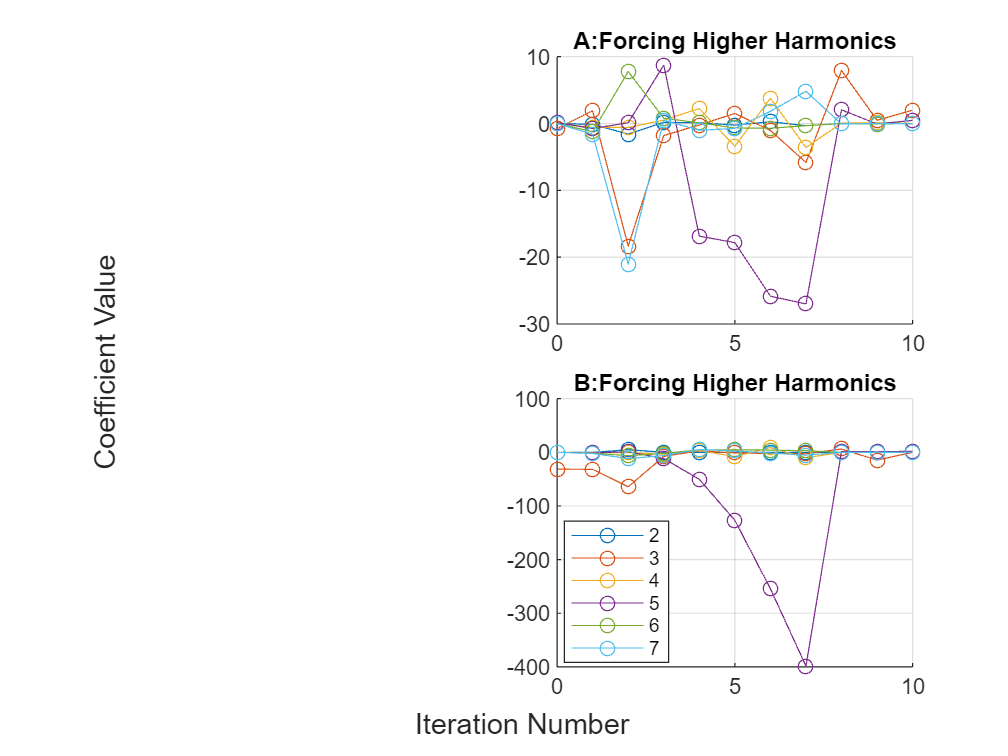

nexttile(2);
hold on;
grid on;
higher_harmonics = (2:control.k_num);
for row = higher_harmonics
    plot(iter_num, A_coeffs(row, :), "-o")
end
title("A:Forcing Higher Harmonics")

nexttile(4);
hold on;
grid on;
for row = (2:control.k_num)
    plot(iter_num, B_coeffs(row, :), "-o")
end
xlabel(t, "Iteration Number")
ylabel(t, "Coefficient Value")
legend(string(higher_harmonics), Location="best")
title("B:Forcing Higher Harmonics")

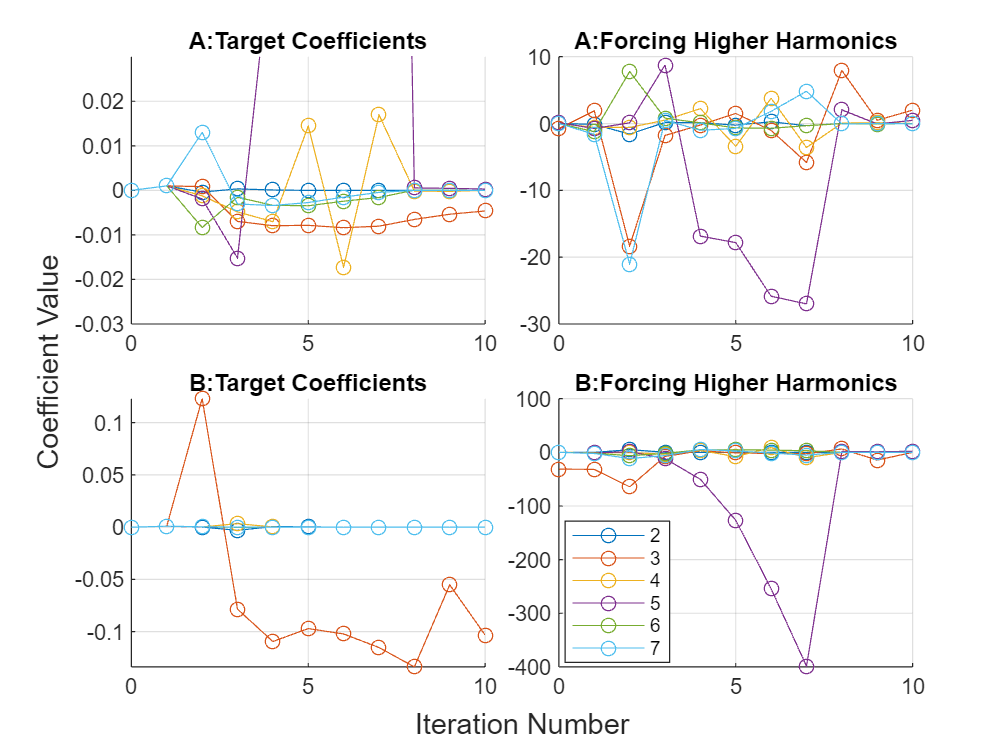

A_coeffs = experiment.A_targets;%(:, 1:harmony_count);
B_coeffs = experiment.B_targets;%(:, 1:harmony_count);
% iter_num = (0:harmony_count-1);
iter_num = (0:size(A_coeffs, 2)-1);
% figure;
% t = tiledlayout(2, 1, "TileSpacing","compact")
nexttile(1);
hold on;
grid on;
higher_harmonics = (2:control.k_num);
for row = higher_harmonics
    plot(iter_num, A_coeffs(row, :), "-o")
end
ylim([-0.03, 0.03])
title("A:Target Coefficients")

nexttile(3);
hold on;
grid on;
for row = (2:control.k_num)
    plot(iter_num, B_coeffs(row, :), "-o")
end
xlabel(t, "Iteration Number")
ylabel(t, "Coefficient Value")
% legend(string(higher_harmonics), Location="northeast")
title("B:Target Coefficients")

% ylim([-0.004, 0.006])

sdafgh

Unrecognized function or variable 'sdafgh'.

## simplified approach

%reset model with given target amplitude
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
experiment = experiment_reset(control);

%tune Kp and Kd and spit out initial run
[input2, trial2, control2] = simple_tuner(model, input, trial, control);

% get response and target
[response, target, inv_score] = get_response_target(input2, trial2, control2);
[control2.Kp, control2.Kd]
    % record data
experiment.A_responses(:, 1) = response(:, 1);
experiment.B_responses(:, 1) = response(:, 2);
experiment.A_targets(:, 1) = target(:, 1);
experiment.B_targets(:, 1) = target(:, 2);

% next run
experiment.A_targets(2:end, 2) = target(2:end, 1).*1.05 + 0.0001;
experiment.B_targets(2:end, 2) = target(2:end, 2).*1.05 + 0.0001;

for i = (2:experiment.harmony_iter)
    % adjust control targets
    control2.target_vec = [experiment.A_targets(:, i), experiment.B_targets(:, i)];
    % run closed loop test
    [input3, trial3] = closedloop_test(model, input2, trial2, control2);
        % adjust next x_init to be last x_value of this run
    trial2.x_init = trial3.X(end, :);

    [response, target, inv_score] = get_response_target(input3, trial3, control2);
    
    "Harmony Loop: " + i + " -> invasiveness: " + inv_score*100
    [response, target]
        % record data
    experiment.A_responses(:, i) = response(:, 1);
    experiment.B_responses(:, i) = response(:, 2);
    

    % break cond
    if abs(inv_score) < invasive_tol
        "Non-invasive control achieved!"
        experiment.A_targets = experiment.A_targets(:, 1:i);
        experiment.B_targets = experiment.B_targets(:, 1:i);
        experiment.A_responses = experiment.A_responses(:, 1:i);
        experiment.B_responses = experiment.B_responses(:, 1:i);
        [response, target]
        break;
    end
        % break cond
    if i == experiment.harmony_iter
        "%%%%%%%%%%%%%%%%%%%%%%%%%%%% COULDNT CONVERGE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%"
        break;
    end

    % set next target
        % secant method
    xn = target;
    xn1 = [experiment.A_targets(:,i-1), experiment.B_targets(:,i-1)];
    fx = response;
    fx1 = [experiment.A_responses(:, i-1), experiment.B_responses(:, i-1)];
    x_new = xn - fx.*((xn-xn1)./(fx-fx1));
    x_new(isnan(x_new)) = 0.001; % Nan proof it
        % only adjust > a2, b2
    experiment.A_targets(2:end, i+1) = x_new(2:end, 1);
    experiment.B_targets(2:end, i+1) = x_new(2:end, 2);
end

[input3, trial3] = closedloop_test(model, input2, trial2, control2);
[response, target, inv_score] = get_response_target(input3, trial3, control2)

plot_CL_inner(input3, trial3, control2)

A_coeffs = experiment.A_responses;%(:, 1:harmony_count);
B_coeffs = experiment.B_responses;%(:, 1:harmony_count);
% iter_num = (0:harmony_count-1);
iter_num = (0:size(A_coeffs, 2)-1);
figure;
t = tiledlayout(2, 1, "TileSpacing","compact")
nexttile;
hold on;
grid on;
higher_harmonics = (2:control.k_num);
for row = higher_harmonics
    plot(iter_num, A_coeffs(row, :), "-o")
end
title("A:Forcing Higher Harmonics")

nexttile;
hold on;
grid on;
for row = (2:control.k_num)
    plot(iter_num, B_coeffs(row, :), "-o")
end
xlabel(t, "Iteration Number")
ylabel(t, "Coefficient Value")
legend(string(higher_harmonics), Location="best")
title("B:Forcing Higher Harmonics")

## ensure non-invasiveness

secant method again

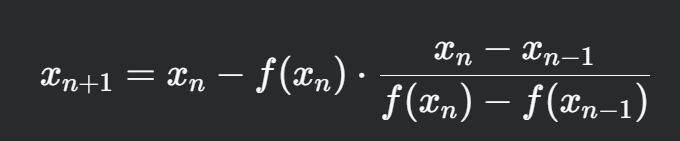

% [model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
% % control.target_amp = target;
% % control.Kp = Kp_init;
% [experiment, input_out, trial_out, control_out] = harmonizer(tracking_tol, invasive_tol, model, input, trial, control)

% control_out.target_vec
% A_coeffs = experiment.A_responses;%(:, 1:harmony_count);
% B_coeffs = experiment.B_responses;%(:, 1:harmony_count);
% % iter_num = (0:harmony_count-1);
% iter_num = (0:size(A_coeffs, 2)-1);
% figure;
% t = tiledlayout(2, 1, "TileSpacing","compact")
% nexttile;
% hold on;
% grid on;
% higher_harmonics = (2:control.k_num);
% for row = higher_harmonics
%     plot(iter_num, A_coeffs(row, :), "-o")
% end
% title("A:Forcing Higher Harmonics")
% 
% nexttile;
% hold on;
% grid on;
% for row = (2:control.k_num)
%     plot(iter_num, B_coeffs(row, :), "-o")
% end
% xlabel(t, "Iteration Number")
% ylabel(t, "Coefficient Value")
% legend(string(higher_harmonics), Location="best")
% title("B:Forcing Higher Harmonics")

% Kd_init = 1.0504e+03;
% control.Kd = Kd_init;
% [input_out, trial_out] = closedloop_test(model, input, trial, control)
% figure;
% plot(trial_out.t_span, trial_out.X(:, 1))

% a = linspace(1, 7.5, 21);

% a = linspace(1, 7.5, 21)
% a(15)
